# Kalman Filter

# Import Data

load('.\indy_20161212_02.mat')

# Preparation

发放率计算、运动分解、分割数据集

unit_spike = reshape(spikes, 1, []);
w = 0.064; % in second
[firing_rates, valid_units, bin_centers] = calculate_firing_rates(unit_spike, t, w); % instant firing rate
filtered_firing_rates = firing_rates(:, valid_units); % filter out those mean rate < 0.5 Hz

[position, velocity, acceleration, kinematics_time] = calculate_kinematics(finger_pos, t, bin_centers);

split_ratio = [0.8, 0.2];
split_ratio = split_ratio / sum(split_ratio);

num_samples = size(filtered_firing_rates, 1);
num_train = round(num_samples * split_ratio(1));

idx = 1:num_samples;

train_idx = idx(1:num_train);
test_idx = idx(num_train+1:end);

train_firing_rates = filtered_firing_rates(train_idx, :);
train_position = position(train_idx, :);
train_velocity = velocity(train_idx, :);
train_acceleration = acceleration(train_idx, :);

test_firing_rates = filtered_firing_rates(test_idx, :);
test_position = position(test_idx, :);
test_velocity = velocity(test_idx, :);
test_acceleration = acceleration(test_idx, :);

# Kalman

Inferring Hand Motion from Multi-Cell Recordings in Motor Cortex using a Kalman Filter

x_k: hidden state [x,y,v_x,v_y,a_x,a_y]'_k

z_k: firing rate

X = [train_position, train_velocity, train_acceleration]';
X1 = X(:,1:end-1);
X2 = X(:,2:end);
Z = train_firing_rates';

m = num_train;

A = (X2*X1')/(X1*X1');
H = (Z*X')/(X*X');
W = (X2 - A*X1)*(X2 - A*X1)'/(m-1);
Q = (Z - H*X)*(Z - H*X)'/m;

# Decoding

Z_test = test_firing_rates';
num_test = num_samples - num_train;
X_est = zeros(6, num_test);
x_init = X(:,end);
P_init = zeros(6, 6);
I = eye(6);

x_prio = zeros(6, 1);
P_prio = zeros(6, 6);
x_post = x_init;
P_post = P_init;
for k=1:num_test
    x_prio = A*x_post;
    P_prio = A*P_post*A' + W;
    K = (P_prio*H')/(H*P_prio*H' + Q);
    x_post = x_prio + K*(Z_test(:,k) - H*x_prio);
    P_post = (I - K*H)*P_prio;
    X_est(:,k) = x_post;
end

predicted_p = X_est(1:2,:)';
predicted_v = X_est(3:4,:)';
predicted_a = X_est(5:6,:)';

# Evaluate

[r2_p, snr_p] = evaluate_decoder_kalman(test_position, predicted_p);
[r2_v, snr_v] = evaluate_decoder_kalman(test_velocity, predicted_v);
[r2_a, snr_a] = evaluate_decoder_kalman(test_acceleration, predicted_a);

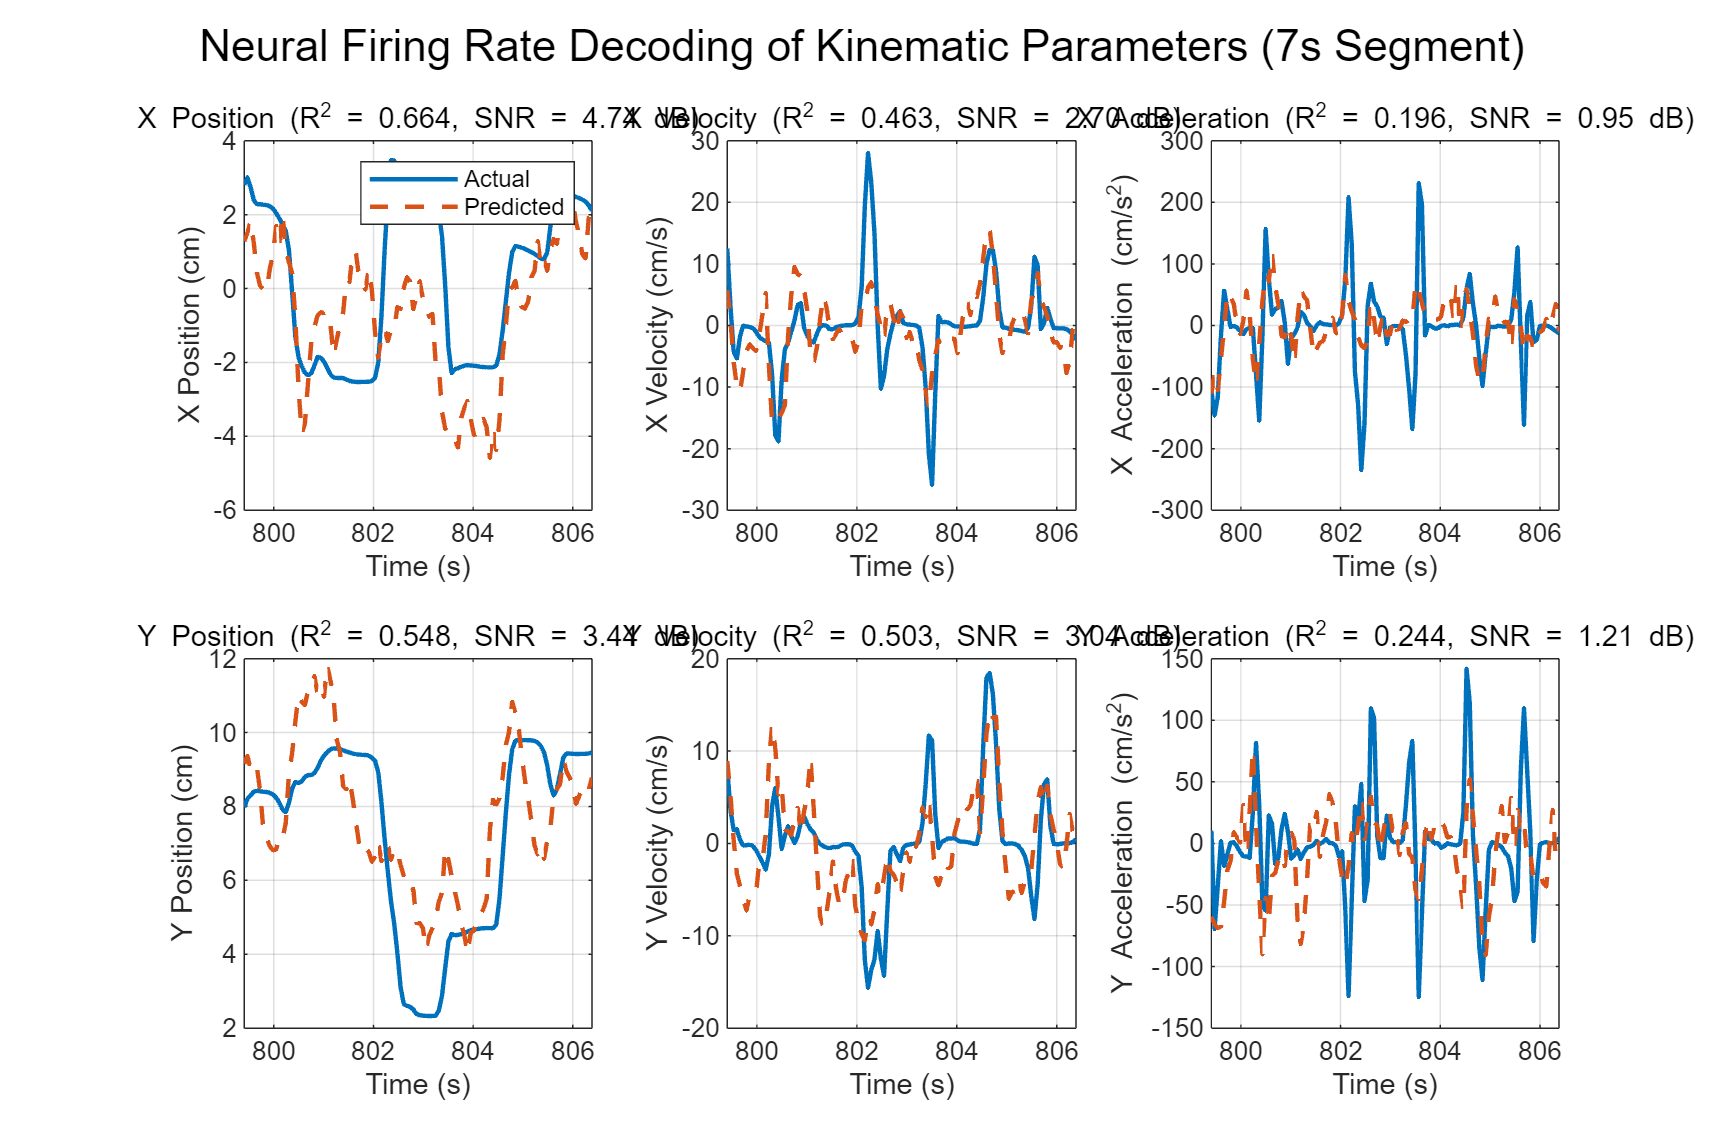

test_time = kinematics_time(test_idx);

% Select middle 7s of the data
total_time_span = test_time(end) - test_time(1);
middle_time = test_time(1) + total_time_span/2;
time_window = 7;
middle_indices = find(test_time >= (middle_time - time_window/2) & test_time <= (middle_time + time_window/2));

% Create a 2×3 subplot arrangement
figure('Position', [100 100 1200 800]);

% Position X
subplot(2,3,1);
plot(test_time(middle_indices), test_position(middle_indices,1), 'LineWidth', 1.5, 'DisplayName', 'Actual');
hold on;
plot(test_time(middle_indices), predicted_p(middle_indices,1), '--', 'LineWidth', 1.5, 'DisplayName', 'Predicted');
title(sprintf('X Position (R^2 = %.3f, SNR = %.2f dB)', r2_p(1), snr_p(1)));
xlabel('Time (s)');
ylabel('X Position (cm)');
legend('Location', 'northeast');
grid on;

% Velocity X
subplot(2,3,2);
plot(test_time(middle_indices), test_velocity(middle_indices,1), 'LineWidth', 1.5, 'DisplayName', 'Actual Velocity');
hold on;
plot(test_time(middle_indices), predicted_v(middle_indices,1), '--', 'LineWidth', 1.5, 'DisplayName', 'Predicted Velocity');
title(sprintf('X Velocity (R^2 = %.3f, SNR = %.2f dB)', r2_v(1), snr_v(1)));
xlabel('Time (s)');
ylabel('X Velocity (cm/s)');
grid on;

% Acceleration X
subplot(2,3,3);
plot(test_time(middle_indices), test_acceleration(middle_indices,1), 'LineWidth', 1.5, 'DisplayName', 'Actual Acceleration');
hold on;
plot(test_time(middle_indices), predicted_a(middle_indices,1), '--', 'LineWidth', 1.5, 'DisplayName', 'Predicted Acceleration');
title(sprintf('X Acceleration (R^2 = %.3f, SNR = %.2f dB)', r2_a(1), snr_a(1)));
xlabel('Time (s)');
ylabel('X Acceleration (cm/s^2)');
grid on;

% Position Y
subplot(2,3,4);
plot(test_time(middle_indices), test_position(middle_indices,2), 'LineWidth', 1.5, 'DisplayName', 'Actual Position');
hold on;
plot(test_time(middle_indices), predicted_p(middle_indices,2), '--', 'LineWidth', 1.5, 'DisplayName', 'Predicted Position');
title(sprintf('Y Position (R^2 = %.3f, SNR = %.2f dB)', r2_p(2), snr_p(2)));
xlabel('Time (s)');
ylabel('Y Position (cm)');
grid on;

% Velocity Y
subplot(2,3,5);
plot(test_time(middle_indices), test_velocity(middle_indices,2), 'LineWidth', 1.5, 'DisplayName', 'Actual Velocity');
hold on;
plot(test_time(middle_indices), predicted_v(middle_indices,2), '--', 'LineWidth', 1.5, 'DisplayName', 'Predicted Velocity');
title(sprintf('Y Velocity (R^2 = %.3f, SNR = %.2f dB)', r2_v(2), snr_v(2)));
xlabel('Time (s)');
ylabel('Y Velocity (cm/s)');
grid on;

% Acceleration Y
subplot(2,3,6);
plot(test_time(middle_indices), test_acceleration(middle_indices,2), 'LineWidth', 1.5, 'DisplayName', 'Actual Acceleration');
hold on;
plot(test_time(middle_indices), predicted_a(middle_indices,2), '--', 'LineWidth', 1.5, 'DisplayName', 'Predicted Acceleration');
title(sprintf('Y Acceleration (R^2 = %.3f, SNR = %.2f dB)', r2_a(2), snr_a(2)));
xlabel('Time (s)');
ylabel('Y Acceleration (cm/s^2)');
grid on;

% Add overall title
sgtitle('Neural Firing Rate Decoding of Kinematic Parameters (7s Segment)');